%Agregar ruta donde se encuentran las funciones que se
%explicaran 
addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Repositorios GIT\Uriel-SIFT\Filtrado");
addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Repositorios GIT\Uriel-SIFT\SIFT");
addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Repositorios GIT\Uriel-SIFT\Explicación del codigo");

## Filtrado y detección de bordes

En esta sección se explicará y demostrará brevemente el funcionamiento de las herramientas implementadas para realizar el filtrado y detección de bordes. El primer paso por supuesto fue realizar una función que llevará a cabo la convolución de una imagen con una mascara dada, a esta se le nombró applyMask, a continuación se da un ejemplo de su uso con una mascara de 3x3 que basicamente lleva a cabo un promedio de los pixeles. 

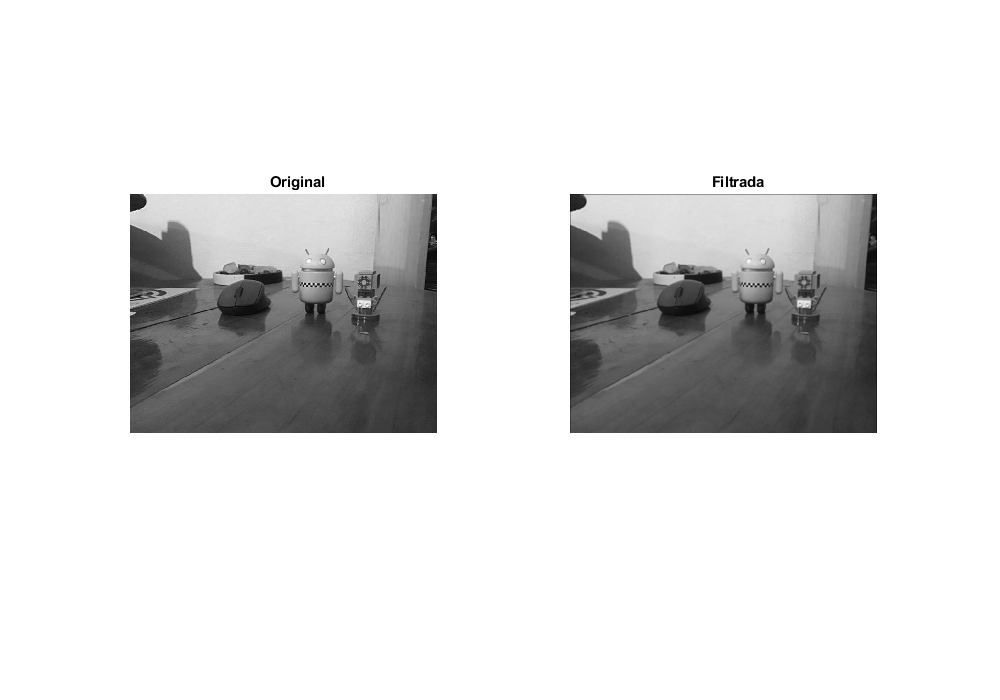

%Se define nuestra mascara de filtrado
avgMask =[1/9,1/9,1/9;1/9,1/9,1/9;1/9,1/9,1/9];
%Leemos la imagen 
img = im2double(imread('im.jpg'));
%Aplicamos el filtro a nuestra imagen usando la función que se implementó 
filteredImg = applyMask(img,avgMask);
%Mostramos la imagen original y la filtrada
h = figure();
set(h, 'Position', [0 0 1000 700])
subplot(1,2,1)
hold on 
title('Original')
imshow(img)
hold off
subplot(1,2,2)
hold on 
title('Filtrada')
imshow(filteredImg)
hold off

Es un quizá un poco dificil notar el efecto, pero si se observa con detalle se podrá notar que la imagen de la derecha presenta un suavizado (quizás sea necesario hacer zoom para apreciarlo). 

Una vez implementada la convolución se procedió a usar esta para implementar los 3 métodos básicos de detección de bordes: Roberts, Prewitt y Sobel. Para esto se creo primero una clase auxiliar que nombramos GradientMethods, la cual contiene simplemente una enumeración con todos los métodos. El método particular se pasa como argumento para la construcción de un objeto de la clase GradientCalculator, la cual aplica la máscara pertinente para obtener los gradientes, a continuación se ejemplifica el computo de dicha clase.

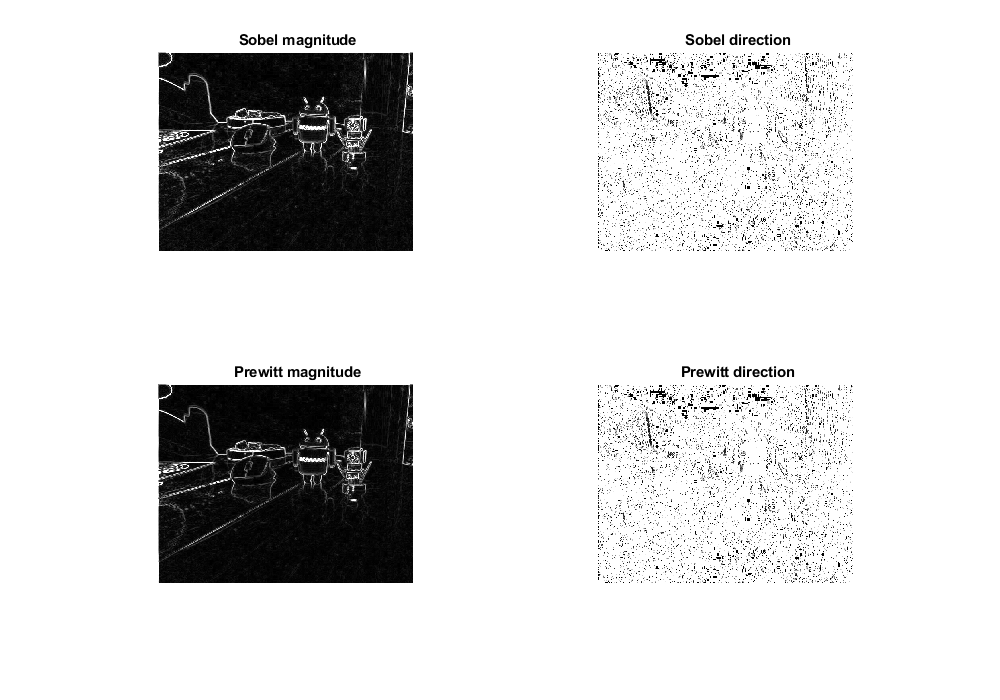

%Se crea una instancia del método particular que se desea utilizar para
%obtener el gradiente
sobelMethod = GradientMethods.SOBEL;
prewittMethod = GradientMethods.PREWITT;

%Calculamos el gradiente con el metodo sobel
gradCalculator = GradientCalculator(sobelMethod);
[sobelMagnitude,sobelDirection] = gradCalculator.obtainGradient(img);

%Calculamos el gradiente con el metodo prewitt
gradCalculator = GradientCalculator(prewittMethod);
[prewittMagnitude,prewittDirection] = gradCalculator.obtainGradient(img);

h = figure();
set(h, 'Position', [0 0 1000 700])
subplot(2,2,1)
hold on 
title('Sobel magnitude')
imshow(sobelMagnitude)
hold off
subplot(2,2,2)
hold on 
title('Sobel direction')
imshow(sobelDirection)
hold off
subplot(2,2,3)
hold on 
title('Prewitt magnitude')
imshow(prewittMagnitude)
hold off
subplot(2,2,4)
hold on 
title('Prewitt direction')
imshow(prewittDirection)
hold off

Finalmente se utilizaron estos métodos de obtención de gradiente para obtener los bordes de la imágen, el proceso es bastante directo, basicamente se define un umbral como una fracción de la magnitud máxima de gradiente, y se descartan aquiellos pixeles que no sean mayores a dicho umbral. El resultado es algo como lo que se muestra a continuación:

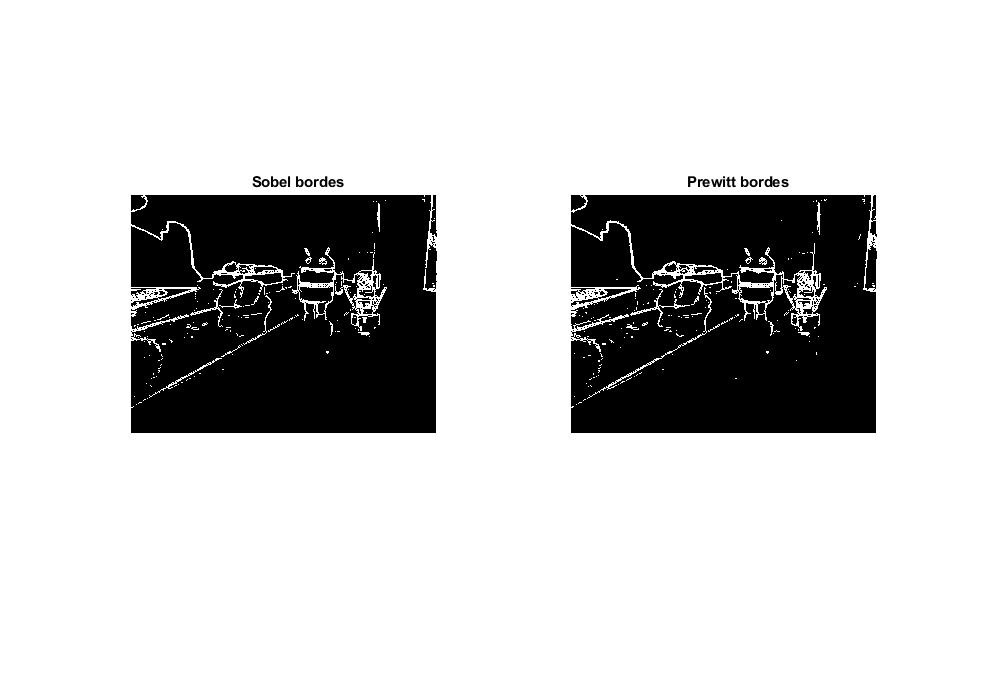

%Se define un detector de bordes con el método que se desee utilizar y un
%threshold
edgeDetector = EdgeDetector(sobelMethod,0.08);
borderImageSobel = edgeDetector.computeEdges(img);
edgeDetector = EdgeDetector(prewittMethod,0.07);
borderImagePrewitt = edgeDetector.computeEdges(img);

h = figure();
set(h, 'Position', [0 0 1000 700])
subplot(1,2,1)
hold on 
title('Sobel bordes')
imshow(borderImageSobel)
hold off
subplot(1,2,2)
hold on 
title('Prewitt bordes')
imshow(borderImagePrewitt)
hold off

## Extracción de características SIFT

Se comenzó la implementación de la extracción de características con SIFT (falta aun la parte del descriptor, es un método algo largo).

### Filtro Gaussiano

La primer parte consistió en implementar la mascara gaussiana, podemos ver que la que se implementó es identica a la que ya viene por defecto en MATLAB:

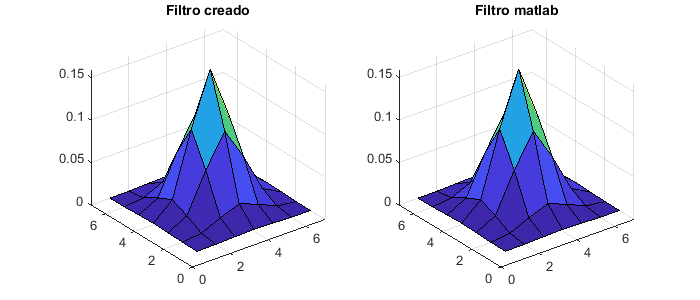

gf = GaussianFilter(1);
matlabGF = fspecial('gaussian',7,1);

h = figure();
set(h, 'Position', [0 0 700 300])
subplot(1,2,1)
surf(gf.mask)
title('Filtro creado')
subplot(1,2,2)
surf(matlabGF)
title('Filtro matlab')

### Obtención de las octavas 

A partir de aquí, como explique brevemente en la presentación de la clase anterior, se debe aplicar repetidamente el filtro gaussiano para diferentes escalas y diferente sigma, con lo cual se obtiene esencialmente un arreglo de imágenes progresivamente mas borrosas, como se muestra a continuación

extractor = SIFTExtractor();
octave = extractor.generateOctave(img,1.6);

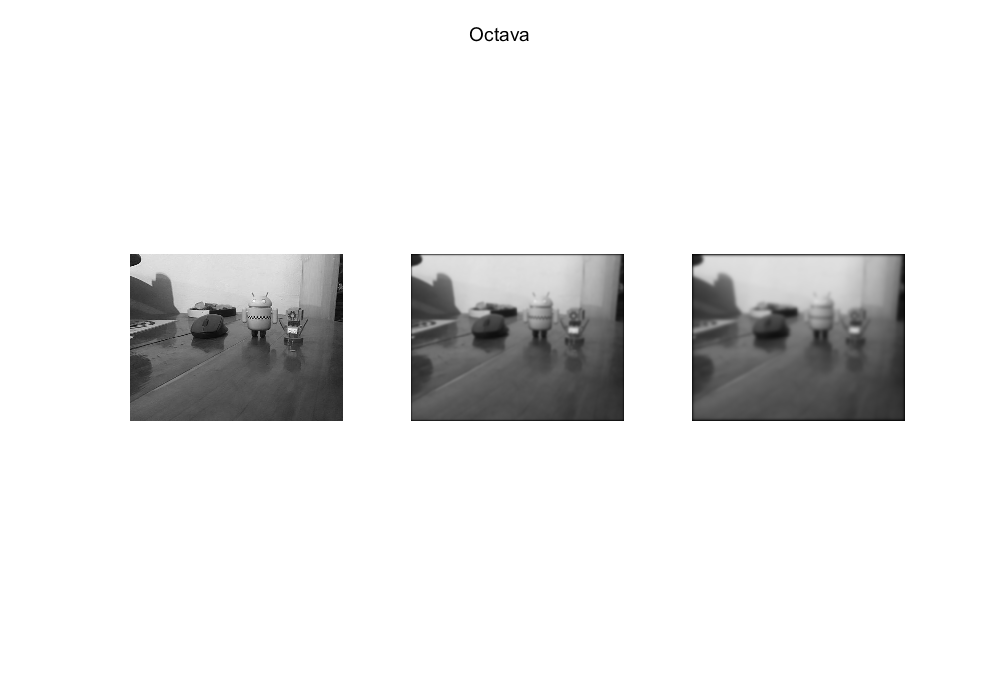

h=figure();
set(h, 'Position', [0 0 1000 700])
sgtitle("Octava")
subplot(1,3,1)
imshow(octave(:,:,1))
subplot(1,3,2)
imshow(octave(:,:,4))
subplot(1,3,3)
imshow(octave(:,:,8))

### Obtención de la diferencia de gaussianas

A partir de las octavas debemos calcular una piramide o montículo de diferencias de gaussianas, lo cual aproxima a la función LoG (Laplaciano de la gaussiana)

%Obtenemos primero una piramide de gaussianas con varias octavas
pyramid = extractor.obtainGaussianPyramid(img,1.6,3);

Blurred image stack completed


%Posteriormente obtenemos la diferencia de gaussianas
dogPyramid = extractor.obtainDoGPyramid(pyramid);

DoG stack completed


dogOctave = dogPyramid{1}

dogOctave = dogOctave(:,:,1) =

   -0.1113   -0.0848   -0.0612   -0.0477   -0.0453   -0.0558   -0.0666   -0.0774   -0.0568   -0.0597   -0.0627   -0.0620   -0.0657   -0.0661   -0.0668   -0.0631   -0.0694   -0.0723   -0.0871   -0.1104   -0.1405   -0.1520   -0.1497   -0.1355   -0.0923   -0.0522   -0.1940   -0.3822   -0.4352   -0.4621   -0.4421   -0.3248   -0.3625   -0.3402   -0.3233   -0.3249   -0.3330   -0.3400   -0.3427   -0.3450   -0.3432   -0.3414   -0.3402   -0.3395   -0.3392   -0.3389   -0.3383   -0.3373   -0.3440   -0.3429   -0.3419   -0.3449   -0.3441   -0.3475   -0.3473   -0.3476   -0.3486   -0.3421   -0.3318   -0.3288   -0.3287   -0.3316   -0.3419   -0.3483   -0.3596   -0.3485   -0.3382   -0.3316   -0.3323   -0.3363   -0.3478   -0.3519   -0.3446   -0.3415   -0.3423   -0.3389   -0.3394   -0.3357   -0.3359   -0.3321   -0.3360   -0.3360   -0.3359   -0.3359   -0.3358   -0.3356   -0.3352   -0.3344   -0.3413   -0.3442   -0.3435   -0.3474   -0.3440   -0.3411   -0.3342   -0.3309   -0.33

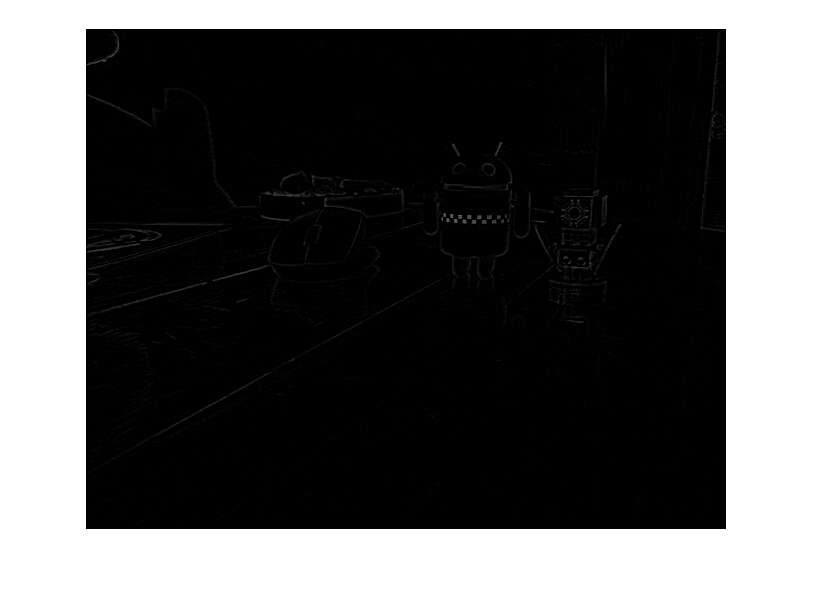

h = figure();
set(h, 'Position', [0 0 1000 700])
sgtitle("DoG")
imshow(dogOctave(:,:,1))

### Extracción de extremos en el espacio de escalas discreto (candidatos)

A partir de aquí lo que se hace es identificar los puntos que presentan un alto valor en el DoG, dentro de la discretización del espacio que se ha realizado, estos realmente inicialmente están pesimamente ubicados, sin embargo despues se hace una interpolación para determinar su ubicación de mejor manera, además de aplicar thresholding y detección de esquinas (Harris), para descartar datos espurios.

candidates = extractor.obtainKeyPointCandidates(dogPyramid{1},0);

[n,~] = size(candidates);

n = 996

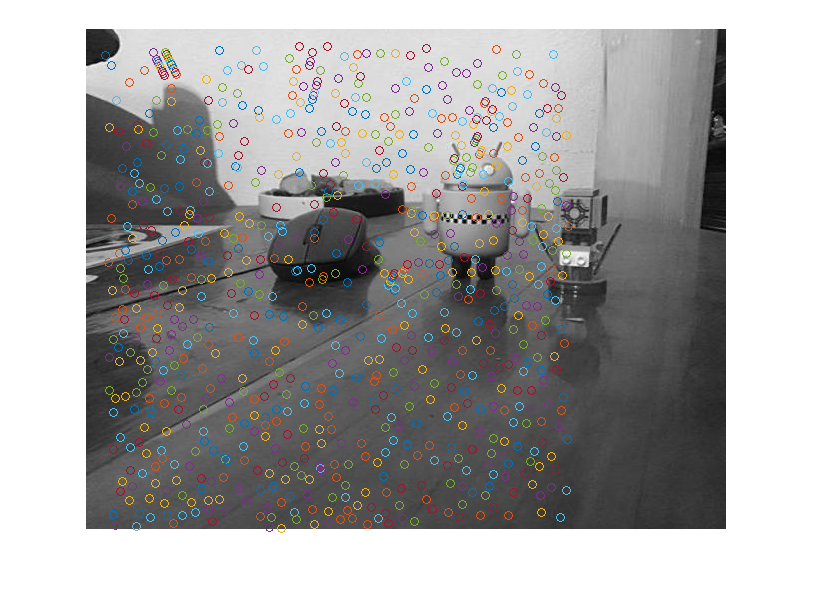

figure()
%Dibuja la imagen 
imshow(img)
%Dibuja todos los puntos
hold on 
for i = 1:n
    candidate = candidates(i,:);
    plot(candidate(1),candidate(2),'o')
end

hold off

### Interpolación, detección de esquinas,  thresholding

keyFeatures = extractor.findKeypointsForPyramid(dogPyramid,0.03,(10+1)^2/10,0);

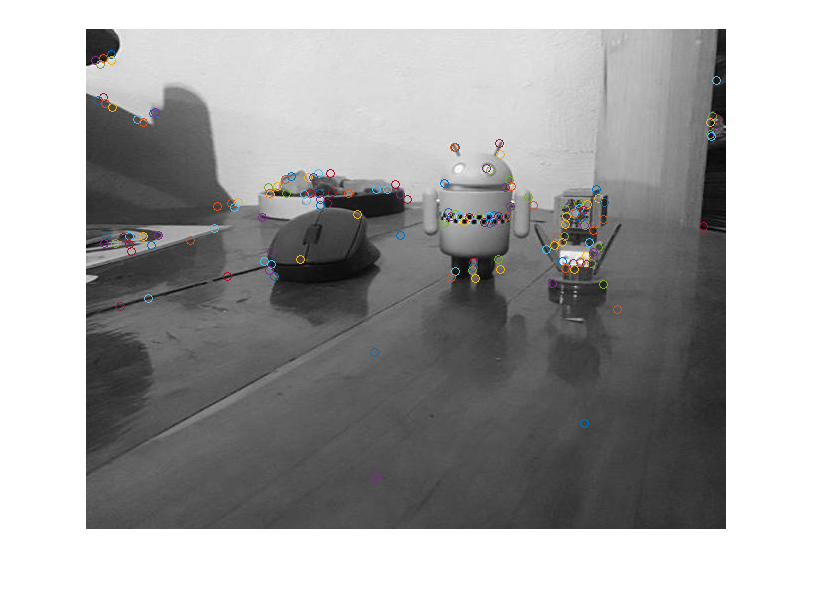


[n,~] = size(keyFeatures);
figure()
%Dibuja la imagen 
imshow(img)
%Dibuja todos los puntos
hold on 
for i = 1:n
    feature = keyFeatures(i,:);
    plot(feature(1),feature(2),'o')
end

hold off

### El paso siguiente es el descriptor pero solo llegue hasta aquí